# [5.6. Поляризация](https://ru.wikipedia.org/wiki/Поляризация_волн)

#### [Формулы Френеля](https://ru.wikipedia.org/wiki/Формулы_Френеля)

Коэффициенты отражения и пропускания, если E параллельно плоскости падения

syms R_p E_pr E_p0 n1 n2 theta1 theta2 T_p E_pt 
R_p==E_pr/E_p0==(n1*cos(theta2)-n2*cos(theta1))/(n1*cos(theta2)+n2*cos(theta1))== ...
    -tan(theta1-theta2)/tan(theta1+theta2)     % коэф. отражения

$$ans = \left(\left(R_{p}=\frac{E_{\mathrm{pr}}}{E_{\mathrm{p0}}}\right)=\frac{n_{1}\,\cos\left(\theta_{2}\right)-n_{2}\,\cos\left(\theta_{1}\right)}{n_{1}\,\cos\left(\theta_{2}\right)+n_{2}\,\cos\left(\theta_{1}\right)}\right)=-\frac{\tan\left(\theta_{1}-\theta_{2}\right)}{\tan\left(\theta_{1}+\theta_{2}\right)}$$

T_p==E_pt/E_p0==2*n1*cos(theta1)/(n1*cos(theta2)+n2*cos(theta1))== ...
2*cos(theta1)*sin(theta2)/(sin(theta1+theta2)*cos(theta1-theta2)) % коэф. пропускния

$$ans = \left(\left(T_{p}=\frac{E_{\mathrm{pt}}}{E_{\mathrm{p0}}}\right)=\frac{2\,n_{1}\,\cos\left(\theta_{1}\right)}{n_{1}\,\cos\left(\theta_{2}\right)+n_{2}\,\cos\left(\theta_{1}\right)}\right)=\frac{2\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{\cos\left(\theta_{1}-\theta_{2}\right)\,\sin\left(\theta_{1}+\theta_{2}\right)}$$

Коэффициенты отражения и преломления, если E перпендикулярны плоскости падения

syms R_o T_o
% R_o = R_|_
% T_o = T_|_
R_o==(n1*cos(theta1)-n2*cos(theta2))/(n1*cos(theta1)+n2*cos(theta2))== ...
    -sin(theta1-theta2)/sin(theta1+theta2)  % коэф. отражения

$$ans = \left(R_{o}=\frac{n_{1}\,\cos\left(\theta_{1}\right)-n_{2}\,\cos\left(\theta_{2}\right)}{n_{1}\,\cos\left(\theta_{1}\right)+n_{2}\,\cos\left(\theta_{2}\right)}\right)=-\frac{\sin\left(\theta_{1}-\theta_{2}\right)}{\sin\left(\theta_{1}+\theta_{2}\right)}$$

T_o==2*n1*cos(theta1)/(n1*cos(theta1)+n2*cos(theta2))== ...
    2*cos(theta1)*sin(theta2)/sin(theta1+theta2)   % коэф. преломления

$$ans = \left(T_{o}=\frac{2\,n_{1}\,\cos\left(\theta_{1}\right)}{n_{1}\,\cos\left(\theta_{1}\right)+n_{2}\,\cos\left(\theta_{2}\right)}\right)=\frac{2\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{\sin\left(\theta_{1}+\theta_{2}\right)}$$

В частности

R_p==R_o==(n1-n2)/(n1+n2) % если theta1=theta2=0

$$ans = \left(R_{p}=R_{o}\right)=\frac{n_{1}-n_{2}}{n_{1}+n_{2}}$$

Для среды с mu~=1 n должен быть в упомянутой выше формуле заменен на n/mu.

#### Интенсивности отраженных и прошедших волн

syms I_R R_p I0_p R_o I0_o I0 I0_p I0_o
% R_o = R_|_
% I0o = I0_|_
I_R==R_p^2*I0_p+R_o^2*I0_o

$$ans = I_{R}=I_{0,o}\,{R_{o}}^{2}+I_{0,p}\,{R_{p}}^{2}$$

I0==I0_p+I0_o    % = интесивность падающей волны

$$ans = I_{0}=I_{0,o}+I_{0,p}$$

syms I_T n1 n2 T_p I0_p T_o I0_o
I_T==n2/n1*(T_p^2*I0_p+T_o^2*I0_o)

$$ans = I_{T}=\frac{n_{2}\,\left(I_{0,o}\,{T_{o}}^{2}+I_{0,p}\,{T_{p}}^{2}\right)}{n_{1}}$$

#### [Угол Брюстера](https://ru.wikipedia.org/wiki/Закон_Брюстера) theta1_p  (угол поляризации)

syms theta1_p n1 n2 theta1 theta2 R_p
tan(theta1_p)==n2/n1

$$ans = \tan\left(\theta_{1,p}\right)=\frac{n_{2}}{n_{1}}$$

theta1+theta2==90

$$ans = \theta_{1}+\theta_{2}=90$$

R_p==0

$$ans = R_{p}=0$$

#### [Закон Малюса](https://ru.wikipedia.org/wiki/Закон_Малюса)

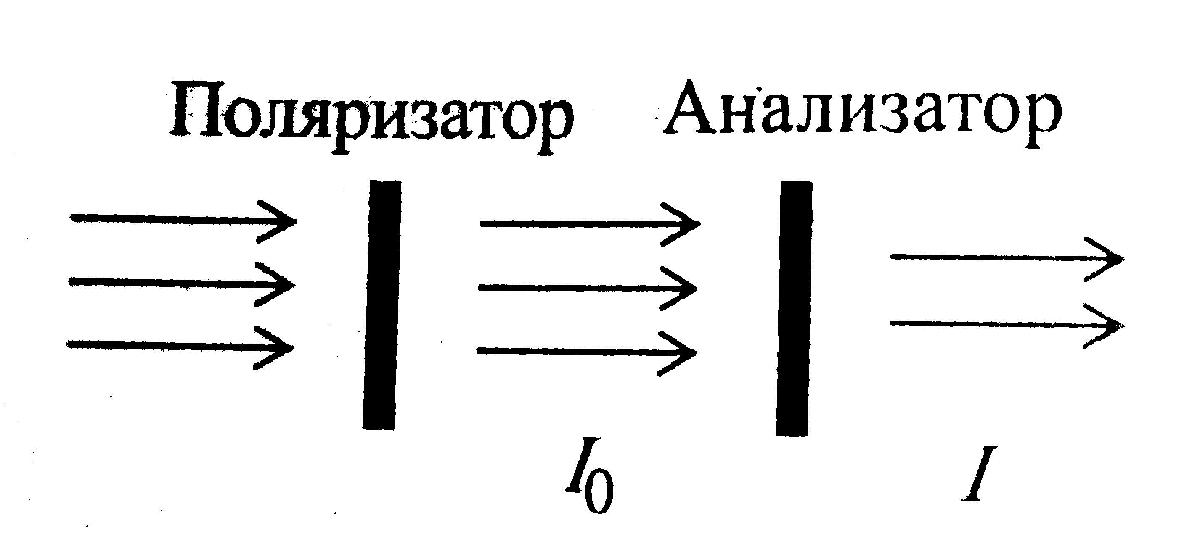

syms I I0 theta
I==I0*cos(theta)^2

$$ans = \text{I}=I_{0}\,{\cos\left(\theta \right)}^{2}$$

% I = интенсивность прошедшей линейно поляризованной волны,
% падающей на поляроид
% theta = угол между направлением поляризации и ориентацией
% анализатора

Степень поляризации

syms P I_max I_min 
P==(I_max-I_min)/(I_max+I_min)

$$ans = P=-\frac{I_{\min}-I_{\max}}{I_{\min}+I_{\max}}$$

#### Пластинки разности хода

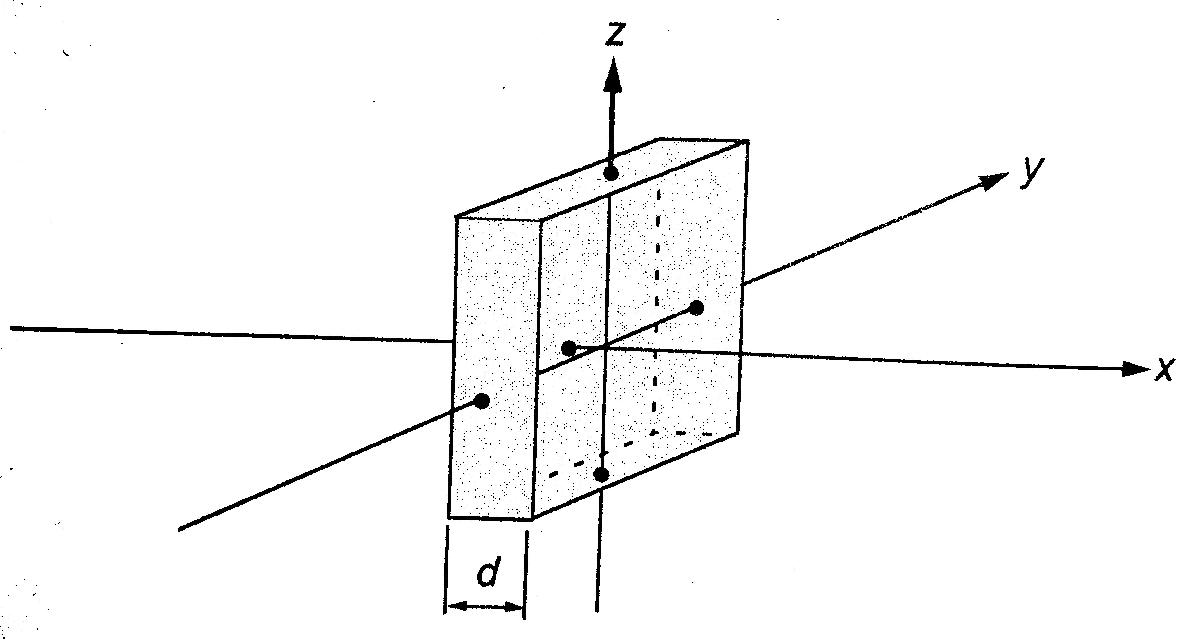

Разность фаз между y- и z- компонентами после пластины с оптической осью, параллельной y-оси

 syms phi d lambda n_o n_co
 phi==(2*pi*d)/lambda*(n_o-n_co)

$$ans = \varphi =-\frac{2\,\pi \,d\,\left(n_{\mathrm{co}}-n_{o}\right)}{\lambda }$$

 % n_o и n_co = показатели преломления обыкновенного
 % и необыкновенного лучей 

*Пример 1.* Плоско поляризованная волна становится эллиптически поляризованной

 syms d lambda m n_o n_co
 d==lambda/4*(1+2*m)/abs(n_o-n_co)

$$ans = d=\frac{\lambda \,\left(2\,m+1\right)}{4\,\left|n_{\mathrm{co}}-n_{o}\right|}$$

 % m = 0,1,2,... 

*Пример 2.* "Отражение" в оптической оси

 d==lambda/2*(1+2*m)/abs(n_o-n_co)

$$ans = d=\frac{\lambda \,\left(2\,m+1\right)}{2\,\left|n_{\mathrm{co}}-n_{o}\right|}$$

 % m = 0,1,2,...